dff =    -2.5588   -2.5595   -2.5586   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000


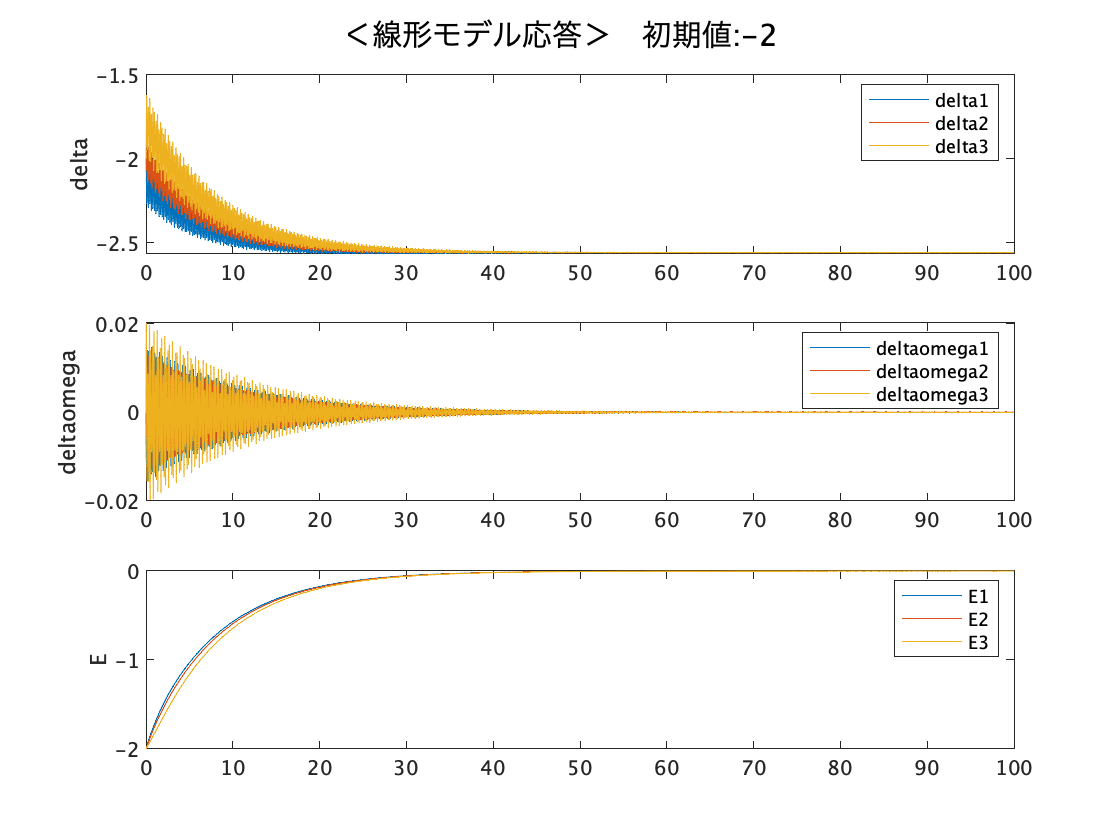

dff =    -1.2795   -1.2796   -1.2794   -0.0000    0.0001   -0.0001   -0.0000   -0.0000   -0.0000


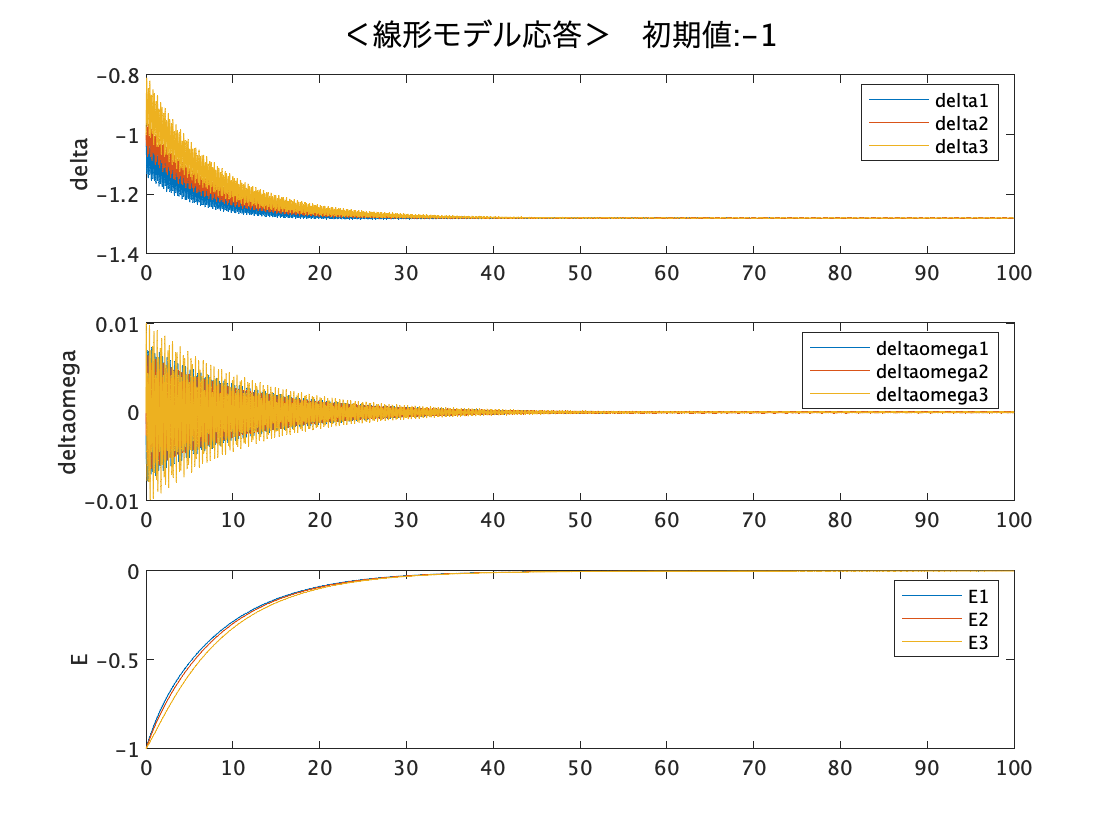

dff =      0     0     0     0     0     0     0     0     0


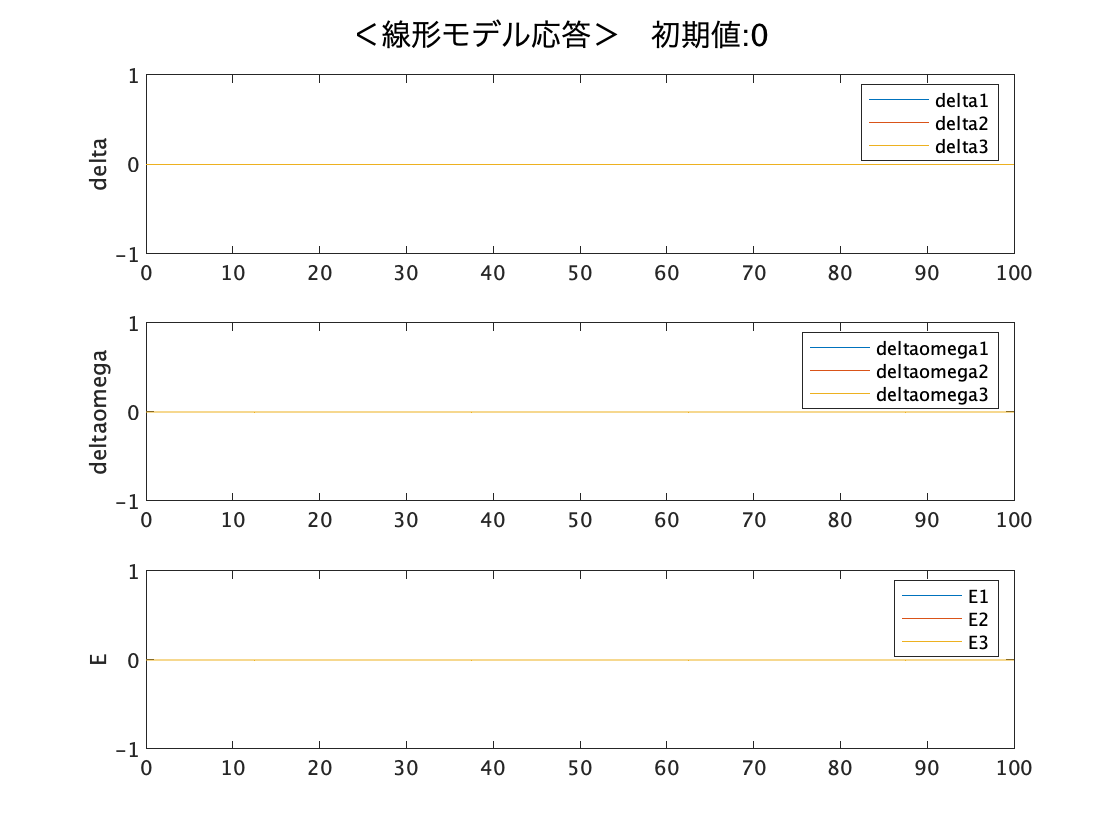

dff =     1.2795    1.2796    1.2794    0.0000   -0.0001    0.0001    0.0000    0.0000    0.0000


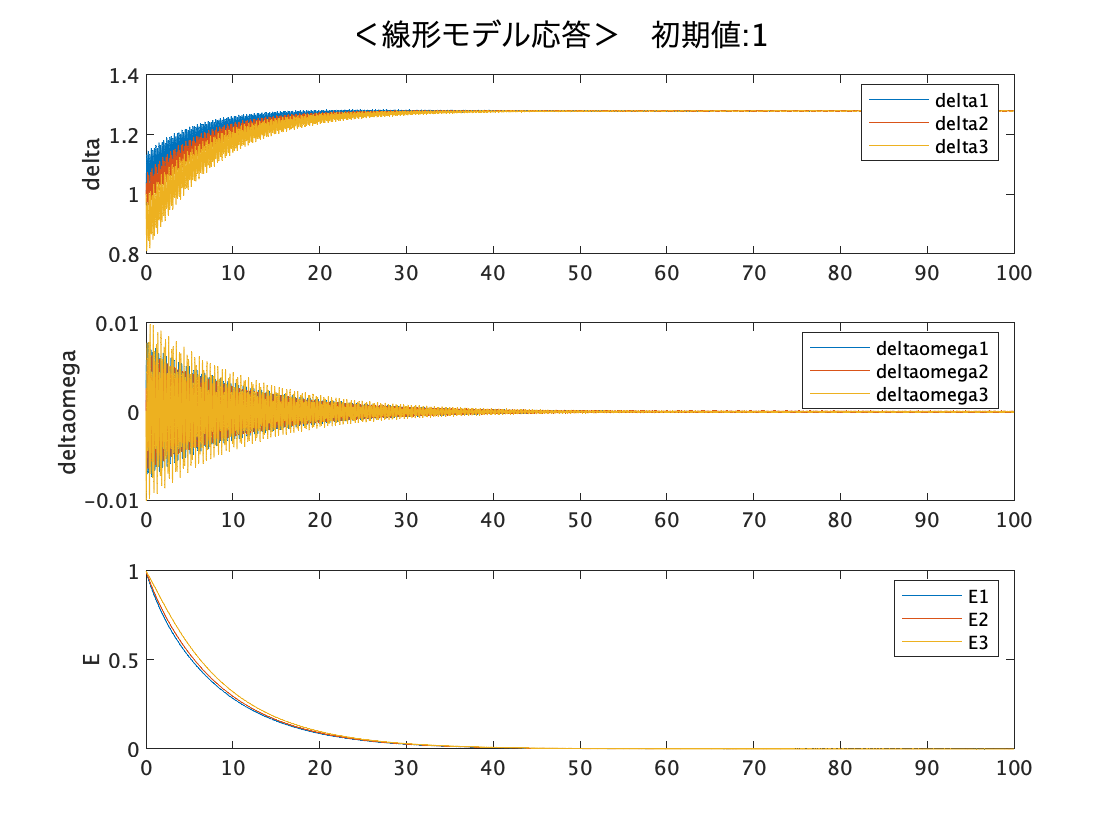

dff =     2.5588    2.5595    2.5586    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000


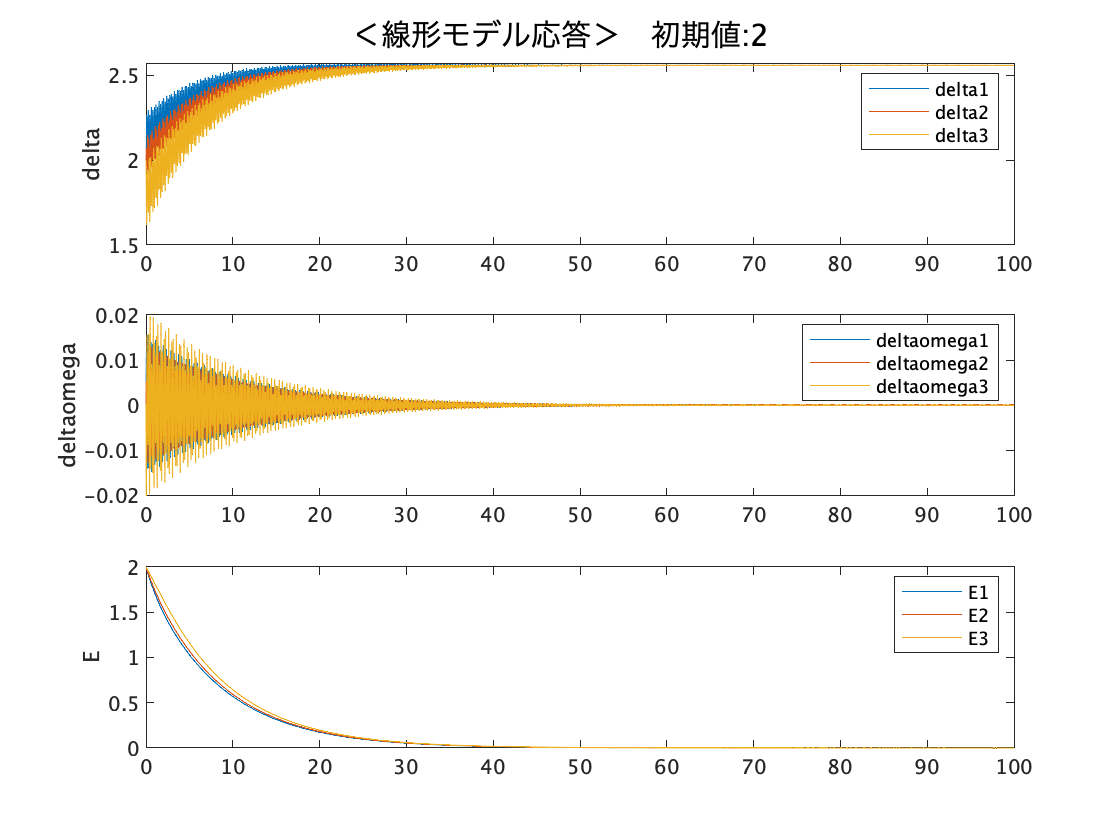

dff =     3.8383    3.8391    3.8381    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000


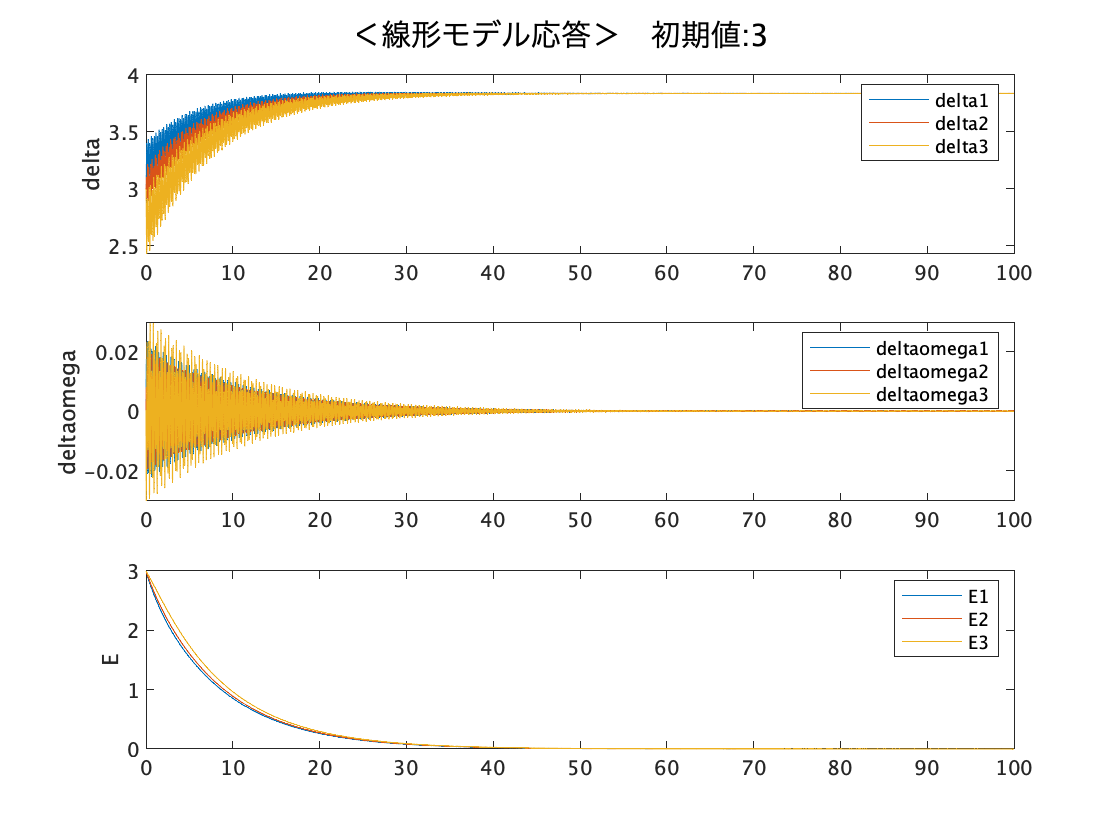

clear

tspan = [0 100];

%定常値を設定
steady_delta = [1.1;1.2;1.4];
steady_deltaomega = [0;0;0];
steady_E = [4;5;3];
steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

psi = get_psi(steady_generator_state);
for cnt = -2:3
    figure;
    dff = plot_generator_state_linear(cnt,tspan,psi)
    sgtitle(['＜線形モデル応答＞　初期値:',num2str(cnt)])
end